clear variables; close all; clc;
s = tf('s')


s =
 
  s
 
Continuous-time transfer function.



G = 10/((1+s)*(1+0.01*s))


G =
 
           10
  ---------------------
  0.01 s^2 + 1.01 s + 1
 
Continuous-time transfer function.



R = (1+s)/s


R =
 
  s + 1
  -----
    s
 
Continuous-time transfer function.



% C = inv(G)
C = (1+s)*(1+0.01*s)/10


C =
 
  0.01 s^2 + 1.01 s + 1
  ---------------------
           10
 
Continuous-time transfer function.



C1 = tf(0)


C1 =
 
  0
 
Static gain.



C2 = (1+s)/(10*(1+0.01*s))


C2 =
 
    s + 1
  ----------
  0.1 s + 10
 
Continuous-time transfer function.



C3 = (1+s)/(10*(1+0.001*s))


C3 =
 
     s + 1
  -----------
  0.01 s + 10
 
Continuous-time transfer function.



C4 = (1+s)*(1+0.01*s)/(10*(1+0.001*s)^2)


C4 =
 
   0.01 s^2 + 1.01 s + 1
  -----------------------
  1e-05 s^2 + 0.02 s + 10
 
Continuous-time transfer function.



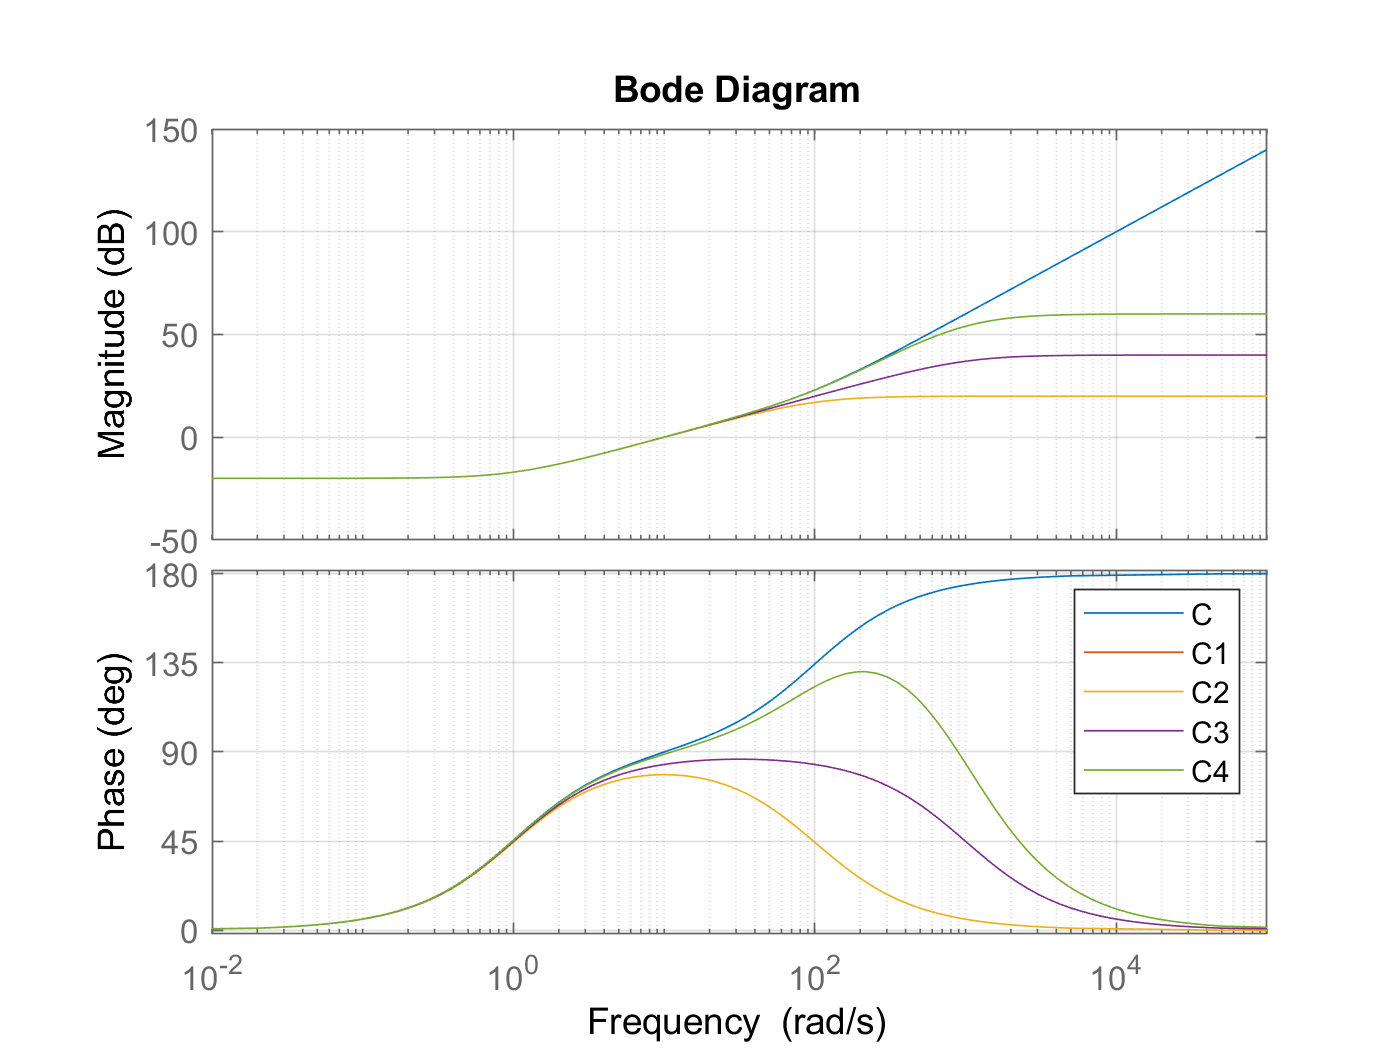

% loop transfer function
L = R*G;

% complementary sensitivity transfer functions
F = (L+C*G)/(1+L);
F1 = (L+C1*G)/(1+L);
F2 = (L+C2*G)/(1+L);
F3 = (L+C3*G)/(1+L);
F4 = (L+C4*G)/(1+L);

% bode plots
figure; bode(C, C1, C2, C3, C4); grid on; legend;

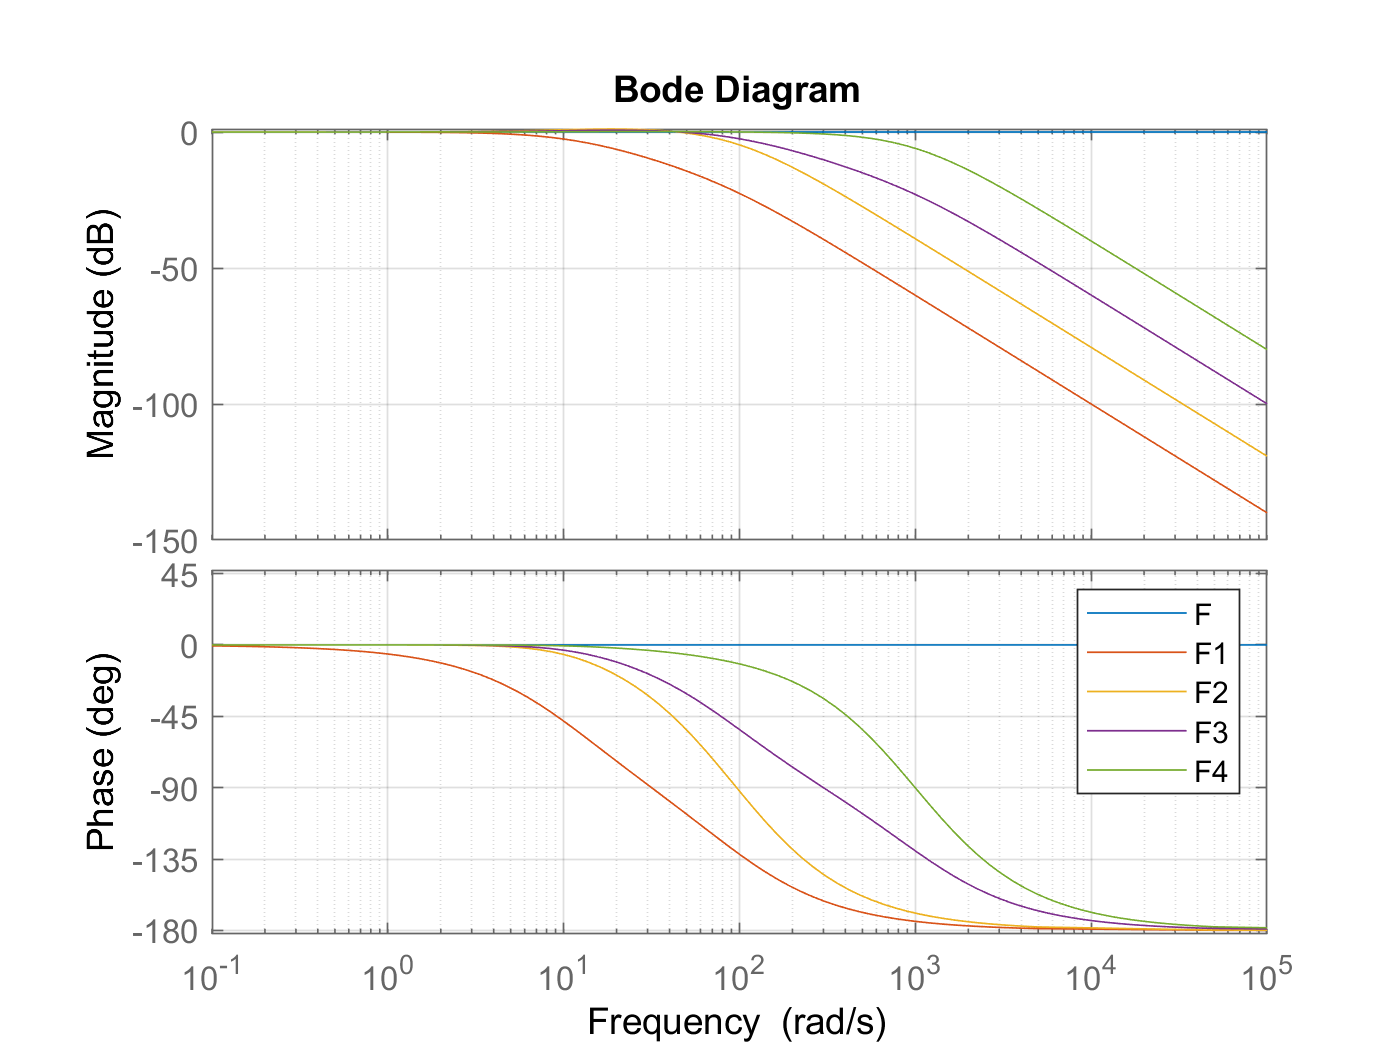

figure; bode(F, F1, F2, F3, F4); grid on; legend;

% frequency response function (frf) at given pulsation
omega = 80;
magnitude = abs([freqresp(F, omega) freqresp(F1, omega) freqresp(F2, omega) freqresp(F3, omega) freqresp(F4, omega)])

magnitude =     1.0000    0.1036    0.7165    0.8408    1.0077


magnitude_db = mag2db(magnitude)

magnitude_db =          0  -19.6923   -2.8954   -1.5058    0.0666


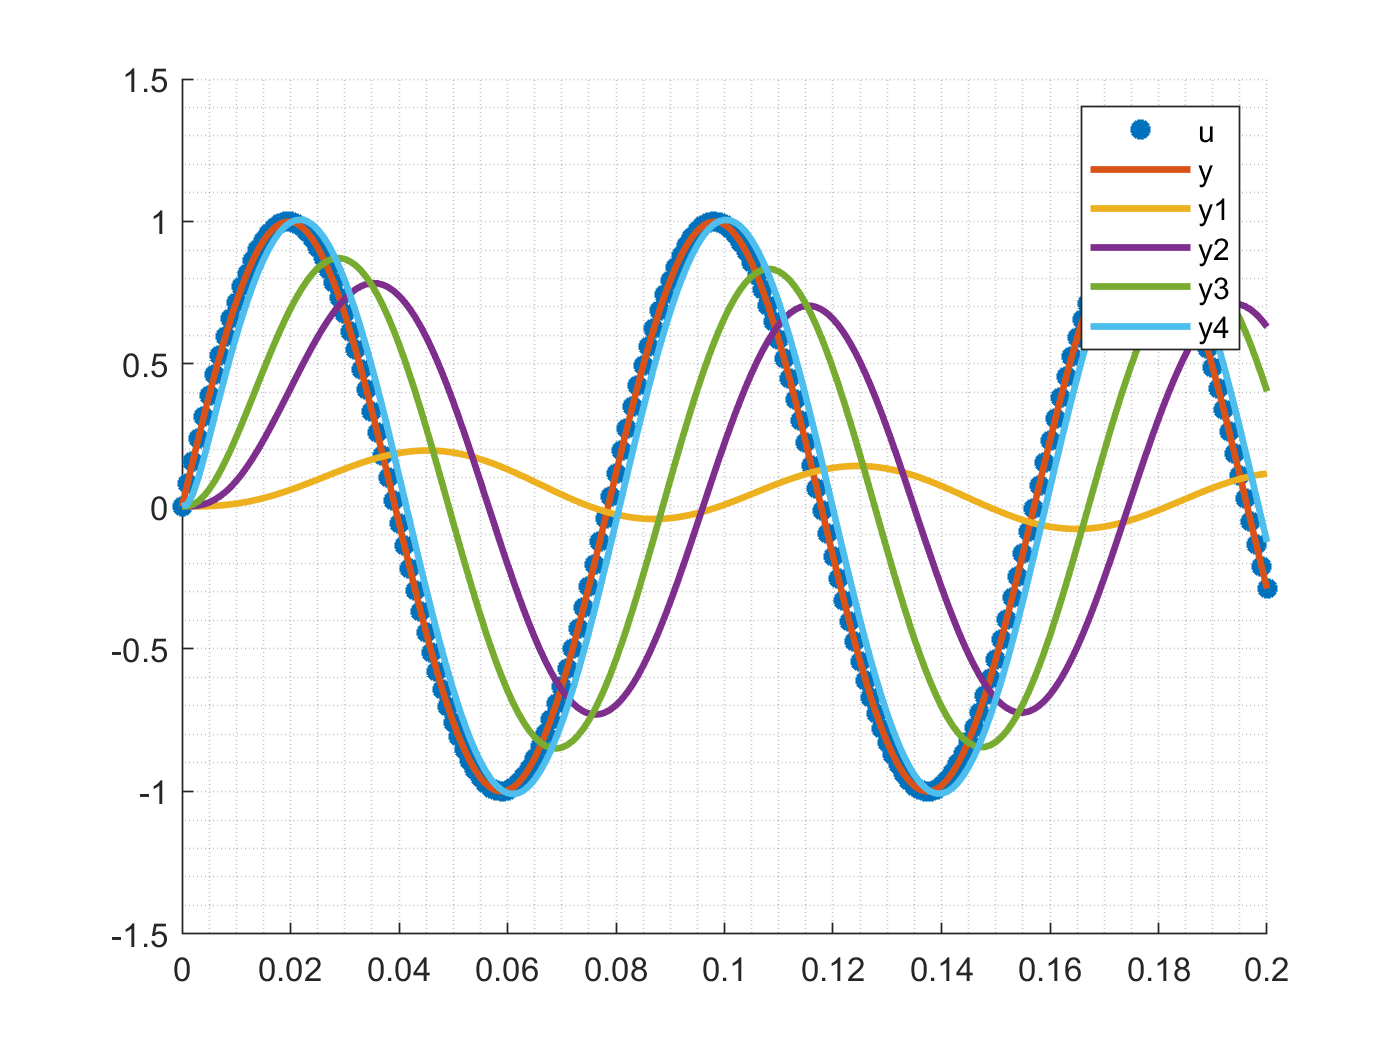

% continous time simulation
dt = 1e-3;
T = 0.2;
time = 0 : dt : T;
u = sin(omega*time);
y = lsim(F, u, time);
y1 = lsim(F1, u, time);
y2 = lsim(F2, u, time);
y3 = lsim(F3, u, time);
y4 = lsim(F4, u, time);
figure; hold on; grid minor;
set(gca, 'DefaultLineLineWidth', 2);
plot(time, u,  '*', 'DisplayName', 'u');
plot(time, y, 'DisplayName', 'y');
plot(time, y1, 'DisplayName', 'y1');
plot(time, y2, 'DisplayName', 'y2');
plot(time, y3, 'DisplayName', 'y3');
plot(time, y4, 'DisplayName', 'y4');
legend;